%MAE 180 PROJ S-3 TEAM CODE

clc
clear
format long
global min_distance;% km
global min_distance_time;
global min_distance_r_s1;
global min_distance_r_s2;
min_distance_time = 0;
min_distance = 50;
min_distance_r_s1 = [0;0;0;];
min_distance_r_s2 = [0;0;0;];


%% Common parameters for both runs
lat = 32.8811913;    % Site latitude (phi) in degrees
alt = 111E-3;        % Site altitude in km
JD_prop = 2460542.7792; % Propagation Julian Date (second value given on file)

%% First Run: Group S-3 (ADVENTURE 1)
% Days (JD), right ascension (ra), declination (dec), and local sidereal time (lst)
JD_s1  = [2460262.842373029;
       2460262.842893863;
       2460262.843414696];
   
ra_s1  = [135.514066681081;
       148.057402685433;
       165.762330451468];

dec_s1 = [29.155447177193;
       45.578290874916;
       56.881276513171];

lst_s1 = [59.199692009582;
       59.387705356210;
       59.575718703254];

%% Second Run: Group K-3 (THE MARTIANS)
% Fill in the missing values with the Group K-3 data
JD_s2  = [2460267.322080967;
       2460267.322601800;
       2460267.323122634];
   
ra_s2  = [192.359369943852;
       206.417534213015;
       226.142267971101];

dec_s2 = [-25.796600080803;
       -26.271136667762;
       -25.487019970794];

lst_s2 = [236.309961929603;
       236.497975276648;
       236.685988623275];
%CONSTANTS
mu= 398600.4354; %km^3/s^2
Rearth= 6378.1366; %km
smallomegaearth= 7.2921159E-5; %rad/s
Areatomassratio= 0.0123; %m^2/kg
JDday2secondconversionunit = 86400; 
J2 = 0.0010826267; %unitless
CD = 1.28; % drag coefficient corrected from annocement 
we = 7.2921159E-5;% Earth's inertial rotation rate

% UCSD coords
lot=deg2rad(-117.2336137);

% convert JD to seconds and units to radians
JD_s1 = JD_s1 * JDday2secondconversionunit;
JD_prop = JD_prop * JDday2secondconversionunit;
lat = deg2rad(lat);
lst_s1 = deg2rad(lst_s1);
ra_s1 = deg2rad(ra_s1);
dec_s1 = deg2rad(dec_s1);

JD_s2 = JD_s2 * JDday2secondconversionunit;
lst_s2 = deg2rad(lst_s2);
ra_s2 = deg2rad(ra_s2);
dec_s2 = deg2rad(dec_s2);

[r0_s1,v0_s1] = gauss(lat, lst_s1, alt, ra_s1, dec_s1, JD_s1, JD_prop);
[r0_s2,v0_s2] = gauss(lat, lst_s2, alt, ra_s2, dec_s2, JD_s2, JD_prop);


% 10. Compute initial orbital elements from r0 and v0
oe0_s1 = ComputeOrbitalElements(r0_s1, v0_s1, mu);
oe0_s2 = ComputeOrbitalElements(r0_s2, v0_s2, mu);


% Initial state vector
y0_s1 = [r0_s1';v0_s1';];
y0_s2 = [r0_s2';v0_s2';];


%% Print initial conditions
fprintf('--- Initial Conditions ---\n');

--- Initial Conditions ---


fprintf('Satellite 1 initial position: [%.6f, %.6f, %.6f] km\n', r0_s1(1), r0_s1(2), r0_s1(3));

Satellite 1 initial position: [2098.703281, 5002.055406, 4219.021380] km


fprintf('Satellite 1 initial velocity: [%.6f, %.6f, %.6f] km/s\n', v0_s1(1), v0_s1(2), v0_s1(3));

Satellite 1 initial velocity: [-0.600570, -4.751516, 5.924891] km/s


fprintf('Satellite 2 initial position: [%.6f, %.6f, %.6f] km\n', r0_s2(1), r0_s2(2), r0_s2(3));

Satellite 2 initial position: [-3769.838526, -4870.572807, 3014.506061] km


fprintf('Satellite 2 initial velocity: [%.6f, %.6f, %.6f] km/s\n', v0_s2(1), v0_s2(2), v0_s2(3));

Satellite 2 initial velocity: [6.352968, -3.803263, 1.828121] km/s




% Satelite 1 starts before satelite 2
% Propegate satelite 1 until the start of satelite 2
% Then propogate them together to find closest distance
A2M_convert = Areatomassratio / 1000000;  % m^2/kg to km^2/kg

JD_init_s1 = JD_s1(2);
JD_init_s2 = JD_s2(2);
t_prop_s1tos2 = JD_init_s2 - JD_init_s1;
tspan_s1tos2 = [0, t_prop_s1tos2];
options = odeset('RelTol',1e-7,'AbsTol',1e-7);
[t_s1tos2, Y_s1tos2] = ode45(@(t, y) one_sat_sim(t, y, mu, J2, Rearth, A2M_convert,CD), tspan_s1tos2, y0_s1, options);

% New positions of our first satelite when the second satelite starts
r0_s1_new = Y_s1tos2(end,1:3);
v0_s1_new = Y_s1tos2(end,4:6);
fprintf('Time propagated from Sat 1 to Sat 2 start: %.6f seconds\n\n', t_prop_s1tos2);

Time propagated from Sat 1 to Sat 2 start: 387046.765717 seconds




% Now propogate the satelites at the same time from the same start time
% Compare the distance between each at every step and find the minimum

JD_init = JD_s2(2);
JD_end = JD_prop;
t_prop = JD_end - JD_init;
tspan = [0, t_prop];
options = odeset('RelTol',1e-7,'AbsTol',1e-7);

y0_big = [r0_s1_new'; v0_s1_new'; y0_s2;];

[t, Y] = ode45(@(t, y) two_sat_sim(t, y, mu, J2, Rearth, A2M_convert,CD), tspan, y0_big, options);

r_end_s1 = Y(end,1:3);
v_end_s1 = Y(end,4:6);
r_end_s2 = Y(end,7:9);
v_end_s2 = Y(end,10:12);

final_distance = norm(r_end_s1 - r_end_s2);

%% Print final conditions and minimum distance report
fprintf('--- Final Conditions ---\n');

--- Final Conditions ---


fprintf('Satellite 1 final position: [%.6f, %.6f, %.6f] km\n', r_end_s1(1), r_end_s1(2), r_end_s1(3));

Satellite 1 final position: [3644.359613, -815.079498, 5763.494111] km


fprintf('Satellite 1 final velocity: [%.6f, %.6f, %.6f] km/s\n', v_end_s1(1), v_end_s1(2), v_end_s1(3));

Satellite 1 final velocity: [-6.458737, -0.465986, 4.005412] km/s


fprintf('Satellite 2 final position: [%.6f, %.6f, %.6f] km\n', r_end_s2(1), r_end_s2(2), r_end_s2(3));

Satellite 2 final position: [-6101.338341, 2112.571515, 2230.572261] km


fprintf('Satellite 2 final velocity: [%.6f, %.6f, %.6f] km/s\n\n', v_end_s2(1), v_end_s2(2), v_end_s2(3));

Satellite 2 final velocity: [-1.346285, -6.946636, 2.902058] km/s



fprintf('Final approach distance between satellites: %.6f km\n', final_distance);
fprintf('Propogated time from satelite 1 r0: [%.6f] s\n', JD_prop - JD_s1(2));

fprintf('--- Minimum Distance Details ---\n');

--- Minimum Distance Details ---


fprintf('Minimum distance encountered: %.6f km\n', min_distance);

Minimum distance encountered: 24.047098 km


fprintf('Time at minimum distance (after Sat 2 start): %.6f seconds\n', min_distance_time);

Time at minimum distance (after Sat 2 start): 1884502.188893 seconds


fprintf('Satellite 1 position at minimum distance: [%.6f, %.6f, %.6f] km\n', min_distance_r_s1(1), min_distance_r_s1(2), min_distance_r_s1(3));

Satellite 1 position at minimum distance: [-626.157607, 6032.005537, 3242.866877] km


fprintf('Satellite 2 position at minimum distance: [%.6f, %.6f, %.6f] km\n', min_distance_r_s2(1), min_distance_r_s2(2), min_distance_r_s2(3));

Satellite 2 position at minimum distance: [-644.529127, 6018.086168, 3236.011123] km


Final distance between satellites: 10771.782855 km


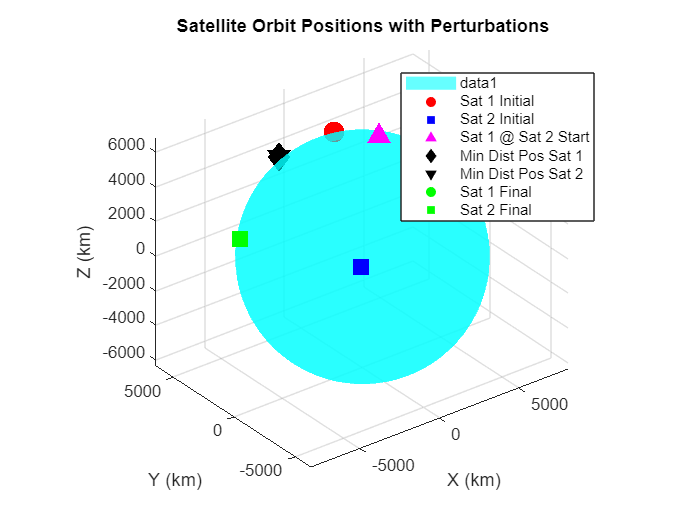


figure;
hold on;

% Plot Earth
[X, Y_earth, Z_earth] = sphere(50);
X = X * Rearth;
Y_earth = Y_earth * Rearth;
Z_earth = Z_earth * Rearth;
surf(X, Y_earth, Z_earth, 'FaceColor', 'c', 'EdgeColor', 'none');
alpha(0.6);

% Plot Satellite 1 Initial Position
scatter3(r0_s1(1), r0_s1(2), r0_s1(3), 150, 'r', 'filled', 'o', 'DisplayName', 'Sat 1 Initial');

% Plot Satellite 2 Initial Position
scatter3(r0_s2(1), r0_s2(2), r0_s2(3), 150, 'b', 'filled', 's', 'DisplayName', 'Sat 2 Initial');

% Plot Satellite 1 Position at Sat 2 Start Time
scatter3(r0_s1_new(1), r0_s1_new(2), r0_s1_new(3), 150, 'm', 'filled', '^', 'DisplayName', 'Sat 1 @ Sat 2 Start');

% Plot Minimum Distance Positions
scatter3(min_distance_r_s1(1), min_distance_r_s1(2), min_distance_r_s1(3), 150, 'k', 'filled', 'd', 'DisplayName', 'Min Dist Pos Sat 1');
scatter3(min_distance_r_s2(1), min_distance_r_s2(2), min_distance_r_s2(3), 150, 'k', 'filled', 'v', 'DisplayName', 'Min Dist Pos Sat 2');

% Plot Final Positions
scatter3(r_end_s1(1), r_end_s1(2), r_end_s1(3), 150, 'g', 'filled', 'o', 'DisplayName', 'Sat 1 Final');
scatter3(r_end_s2(1), r_end_s2(2), r_end_s2(3), 150, 'g', 'filled', 's', 'DisplayName', 'Sat 2 Final');

% Configure the plot
xlabel('X (km)');
ylabel('Y (km)');
zlabel('Z (km)');
title('Satellite Orbit Positions with Perturbations');
grid on;
axis equal;
legend('Location', 'best');
view(3);
hold off;